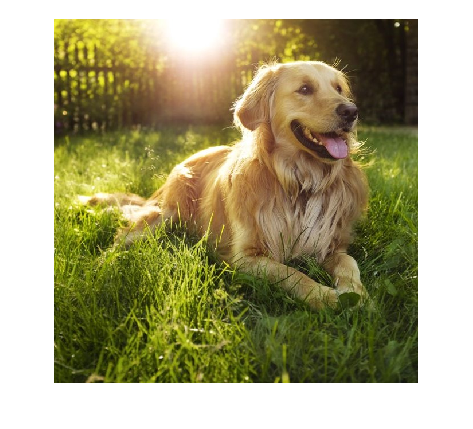

img = imread("squaredog.jpg");
imshow(img);

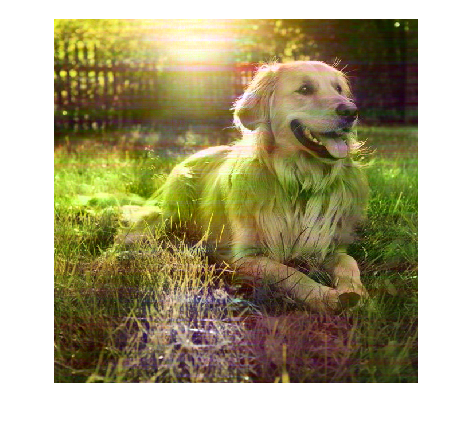


R = im2double(img(:,:,1));
G = im2double(img(:,:,2));
B = im2double(img(:,:,3));

[U,S,V] = svd(R);
RK = U*V';
RM = V*S*V';

[U,S,V] = svd(G);
GK = U*V';
GM = V*S*V';

[U,S,V] = svd(B);
BK = U*V';
BM = V*S*V';


% for i = 1:size(K,1)
%     for j = 1:size(K,2)
%         if i < j-300 || i > j + 300
%             M(i,j) = 0;
%         end
%     end
% end

R = GK*RM;
G = RK*GM;
B = GK*BM;


outimg = cat(3,R,G,B);
imshow(outimg);

%colormap("gray")


%imshow();

